## Вариант 1

### Задача 1

Определить коэффициент запаса прочности болта M14х1,5, на котором подвешен блок, через который поднимают груз массой 100 кг. Болт предварительно не затянут. Предел текучести стали, из которой изготовлен болт, 300 МПа.

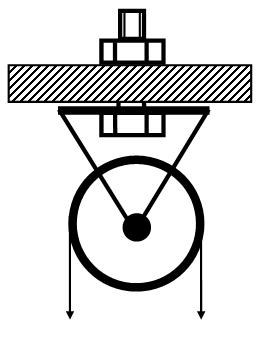

Параметры резьбы М14х1,5:

- номинальный диаметр - 14

- средний диаметр - 13,026

- диаметр по впадинами - 12,16

g = 9.81;
pi = pi;
m = 100;
d3 = 12.16;
s_lim = 300;

F = 2*m*g

F = 1962

A = 0.25*pi*d3^2

A = 116.1334

sig = F/A

sig = 16.8944

S = s_lim/sig

S = 17.7574

### Задача 2

Зубчатое колесо установлено на вал диаметром d=40 мм с помощью соединения с натягом. При работе на колесо действуют тангенциальная Ft=2500 Н и осевая Fz=900 силы.

Рассчитать из условия отсутствия сдвига минимальный натяг, с которым колесо необходимо надеть на вал.

Ширина колеса l=40 мм, делительный диаметр колеса d2 = 120 мм. Материал вала и колеса - сталь (E=210000 МПа, *μ*=0,3).

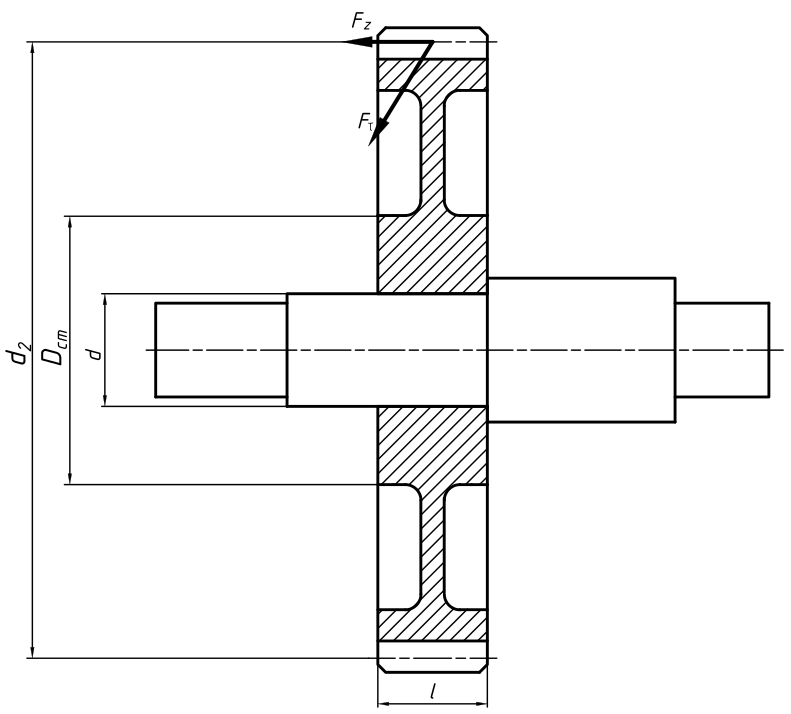

Для решения необходимо определить переменные, заданные в шаблоне (c1, c2, p, N)

d = 40;
l = 40;
d2 = 120;
Dst = 60;
Ft = 2500;
Fz = 900;
f = 0.12;
E1 = 2.1e5;
E2 = 2.1e5;
mu1 = 0.3;
mu2 = 0.3;

c1 = 0.7

c1 = 0.7000

c2 = (1 + (d/Dst)^2)/(1 - (d/Dst)^2) + mu2

c2 = 2.9000

T = Ft*d2/2000

T = 150


p = (((2000*T/d)^2 + Fz^2)^0.5)/(f*pi*d*l)

p = 12.5232


N = p*1000*d*(c1/E1+c2/E2)

N = 8.5873

### Задача 3

Стальной двутавр длиной L = 500 мм приварен к стенке двумя угловыми швами сверху и снизу. На двутавр действует сила F=4 000 Н. Размеры двутавра h=50 мм, b=12 мм. Рассчитать катет сварного шва при условии, что допустимое напряжение $\left\lbrack \tau \right\rbrack =100\textrm{МПа}$.

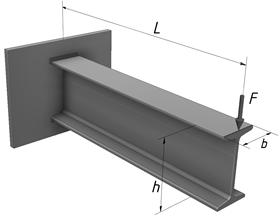

L = 500;
F = 400;
h = 50;
b = 12;
t_lim = 100;

k = (((F*L/h)^2 + (F/2)^2)^0.5)/(0.7*b*t_lim)

k = 4.7679

## Вариант 2

### Задача 1

Шпилька с номинальным диаметром 12 мм ввёрнута в абсолютно жесткое основание. На неё с зазором надета втулка и притянута гайкой. Внутренний диаметр втулки – 12,5 мм, наружный – 23 мм Усилие затяжки в шпильке равно 8000 Н. Втулка и шпилька изготовлены из стали одной марки. Определите максимальное значение силы F, при котором втулка ещё будет оказывать давление на основание.

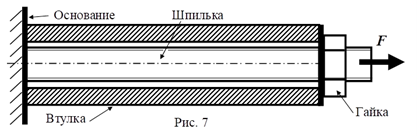

Ft = 8000;
d = 12;
P = 1.75;
d3 = d - 1.227*P;
d_in = 12.5;
D_ou = 23;

A_bolt = pi*d3^2/4

A_bolt = 76.2438

A_bush = 0.25*pi*(D_ou^2 - d_in^2)

A_bush = 292.7572


chi = 1/A_bush/(1/A_bolt+1/A_bush)

chi = 0.2066

F = Ft/(1-chi)

F = 1.0083e+04

### Задача 2

Кронштейн, служащий для удержания подвесного груза на стене, устанавливается на четыре винта. К нему подвершен груз массой m=300 кг. Найти необходимую силу затяжки винтов по условию нераскрытия стыка, приняв что кронштейн стальной, а стена бетонная. Коэффициент основной нагрузки принять равным 0,7. Размеры ***l***=500 мм, ***w***=200 мм, ***b***=20 мм, ***h***=400 мм, ***a***=390 мм. Коэффициент запаса по нераскрытию ***k*** принять 1,5.

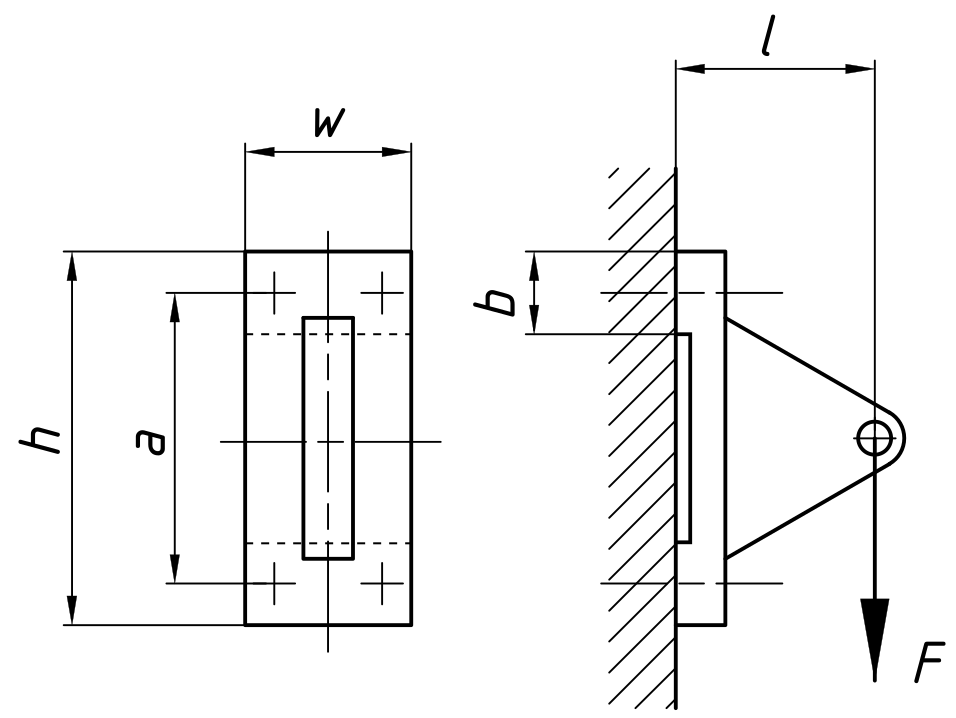

m = 300;
g = 9.81;
chi = 0.7;
l = 500;
w = 200;
h = 400;
a = 390;
b = 20;
k = 1.5;

F = m*g

F = 2943


W = (2*w*b*0.25*a^2)/h*2

W = 1521000


A = 2*w*b

A = 8000


sig_T = (1-chi)*F*l/W

sig_T = 0.2902


sig_tight = sig_T*k

sig_tight = 0.4354


F_tight = sig_tight*A/4

F_tight = 870.7101


F_tight2 = k*(1-chi)*F*l/(2*a)

F_tight2 = 848.9423

### Задача 3

Отводной патрубок трубы, находящей под давлением *p*=5 МПа, заглушен крышкой, приваренной по контуру. Определите минимально допустимую толщину обода крышки *k*, если значение допустимого касательного напряжения для металла сварного шва равно $\left\lbrack \tau \right\rbrack$=120 МПа, а диаметр крышки *d=*300 мм. Толщина стенки патрубка $\delta$ = 10 мм.

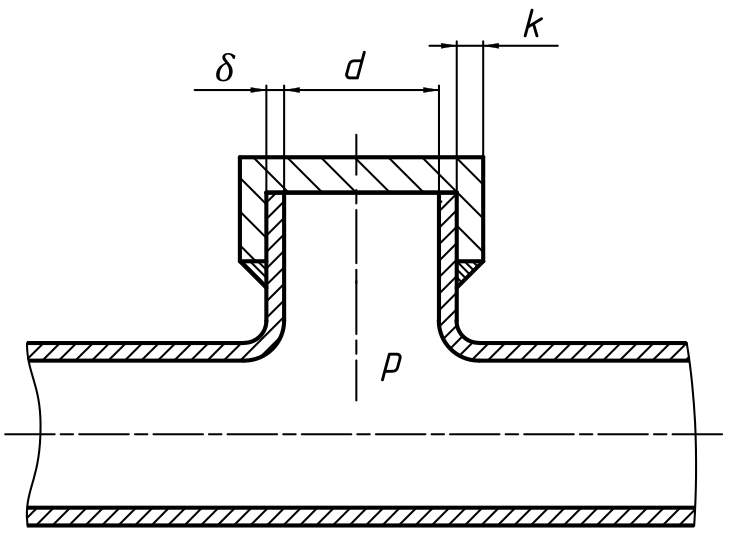

p = 5;
delta = 10;
d = 300;
t_lim = 120;

A = pi*d^2*0.25

A = 7.0686e+04


F = p*A;

k = F/(pi*(d+2*delta)*t_lim)

k = 2.9297

## Вариант 3

### Задача 1

К стальной потолочной плите болтом притянут блок, посредством которого поднимают груз массой 50 кг. Определите усилие затяжки и минимально допустимый диаметр болта по впадинам резьбы из условия нераскрытия стыка между основанием блока и плитой. Коэффициент запаса по нераскрытию стыка принять равным 2. Коэффициент основной нагрузки равен 0,2. Предел текучести стали, из которой изготовлен болт, 300 МПа. Коэффициент запаса по текучести должен быть не менее 1,5.

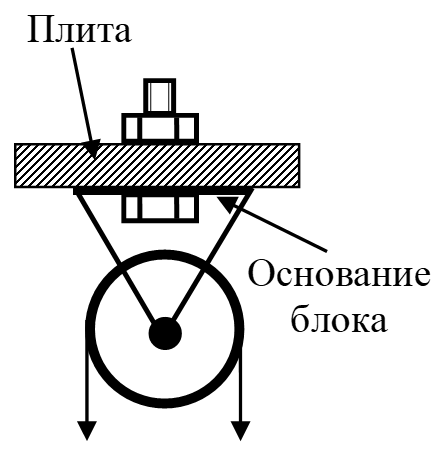

m = 50;
g = 9.81;
k = 2;
chi = 0.2;
s_lim = 300;
s = 1.5;

F_tight = k*m*2*g*(1-chi)

F_tight = 1.5696e+03


F_sum = 1.3*F_tight + chi*m*2*g

F_sum = 2.2367e+03


s_av = s_lim/s

s_av = 200


d3 = (4*F_sum/(pi*s_av))^0.5

d3 = 3.7735

### Задача 2

При обработке на станке деталь зажимают в машинные тиски. Найти силу, которую необходимо приложить на рычаге длиной l=250 мм для удержания детали в тисках, при условии, что деталь вырывает при резании с силой 900 Н. Зажи детали осуществляется при помощи передачи винт-гайка на основе трапециидальной резьбы Тр22х3. Коэффициент трения между деталью и губками тисков принять 0,25. Коэффициент трения в резьбе – 0,1, трением на торце винта пренебречь.

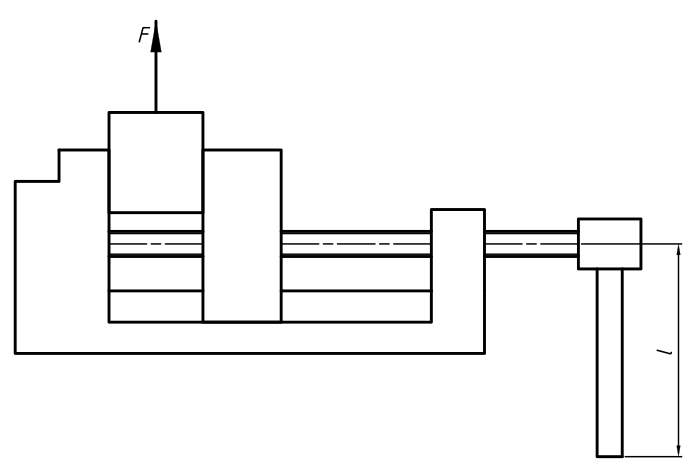

F = 900;
f1 = 0.25;
f2 = 0.1;
d = 22;
P = 3;
l = 250;
hamma = pi/6;

d2 = d- 0.5*P

d2 = 20.5000


F_tight = F/(2*f1)

F_tight = 1800


T_tight = 0.5*F_tight*tan(atan(P/(pi*d2)) + atan(f2/cos(hamma)))*d2/1000

T_tight = 3.0060


F_man = T_tight/l*1000

F_man = 12.0241

### Задача 3

Барабан канатного подъемника состоит из трех деталей, скрепленных между собой резьбовым соединением. Детали барабана устанавливаются на вал с натягом. Рассчитать минимальный натяг в соединении, если на канат действует сила F=3 000 Н. Номинальный диаметр соединения d=50 мм. Размеры l1=l2=40 мм, диаметр ,барабана D=400 мм. Коэффициент трения в соединении f=0,3.

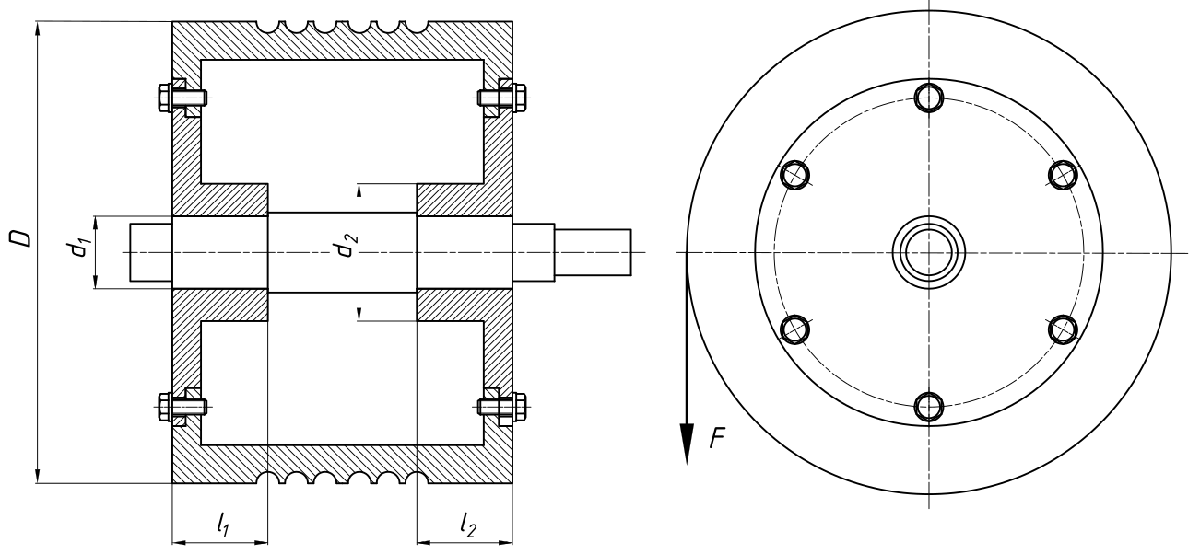

F = 3000;
D = 400;
f = 0.3;
d = 50;
l1 = 40;
l2 = 40;
d2 = 75;
E1 = 2.1e5;
E2 = 2.1e5;
mu1 = 0.3;
mu2 = 0.3;

c1 = 0.7

c1 = 0.7000

c2 = (1 + (d/d2)^2)/(1 - (d/d2)^2) + mu2

c2 = 2.9000

T = F*D/2000

T = 600


p = (2000*T/d)/(f*pi*d*(l1+l2))

p = 6.3662


N = p*1000*d*(c1/E1+c2/E2)

N = 5.4567

Рычажно-винтовой домкрат используют для поднятия автомобиля массой 2000 кг. Шаг винта с упорной резьбой в домкрате p=3 мм. Найти необходимую силу на рычаге домкрата при условии, что КПД передачи η=0,3. Угол β=90°, длина рычагов l = 300 мм.

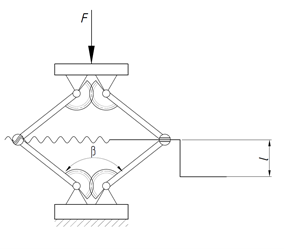

m = 2000;
p = 3;
eff = 0.3;
beta = pi/2;
l = 300;
g = 9.81;

Fb = m*g*tan(beta/2)

Fb = 1.9620e+04

T = Fb*p/(eff*2*pi)

T = 3.1226e+04

F_l = T/l

F_l = 104.0873

Требуется определить максимальное значение силы Р, которое выдержит соединение с натягом при максимально возможном натяге. Стальной стержень вставлен с натягом в стальную плиту методом запрессовки. Толщина плиты h=100 мм. Диаметр отверстия в плите равен 60±0,006 мм. Диаметр стержня 60,05±0,006. Модуль упругости стали Е=200000 МПа

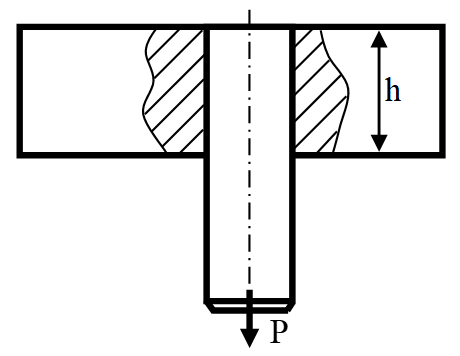

h = 100;
d = 60;
E = 2e5;

ei = -6;
es = 6;
EI = 44;
ES = 56;
Nmax = ES - ei

Nmax = 62

c1 = 0.7;
c2 = 1.3;
p = Nmax*1e-3*E/(d*(c1+c2))

p = 103.3333

P = p*pi*d*h

P = 1.9478e+06